G(z)

num = [ 1  -1 ];
den = [ 1  -1.85  0.9 ];
H = tf(num,den,0.1)

H =
 
        z - 1
  ------------------
  z^2 - 1.85 z + 0.9
 
Sample time: 0.1 seconds
Discrete-time transfer function.



G(z) another approach

z = tf('z',0.1);
H = (z - 1) / (z^2 - 1.85*z + 0.9);

Z Transform

syms n
f = sin(n);
ztrans(f)

$$ans = \frac{z\,\sin\left(1\right)}{z^{2}-2\,\cos\left(1\right)\,z+1}$$

Z Transform with symbolic variable

syms z a
F = 1/(a*z);
iztrans(F)

$$ans = \frac{\delta_{n-1,0}}{a}$$

Symbolic Function

syms f(x,y)
f(x,y)=x^2*y

$$f(x, y) = x^{2}\,y$$

f(3,2)

$$ans = 18$$

**Inverse Z-Transform of Symbolic Function**

If `iztrans` cannot compute the inverse transform, it returns an unevaluated call.

syms f1(x) f2(x) a b
f1(x) = exp(x);
f2(x) = x;
iztrans([f1, f2],x,[a, b])

$$ans = \left(\begin{array}{cc} \mathrm{iztrans}\left({\mathrm{e}}^{x},x,a\right) & \mathrm{iztrans}\left(x,x,b\right) \end{array}\right)$$

Inverse Z Transform

syms z
F = 2*z/(z-2)^2;
iztrans(F)

$$ans = 2^{n}+2^{n}\,\left(n-1\right)$$

figure
e1=zpk([],0,1)

e1 =
 
  1
  -
  s
 
Continuous-time zero/pole/gain model.



e2=zpk([],0,1,'iodelay',1)

e2 =
 
              1
  exp(-1*s) * -
              s
 
Continuous-time zero/pole/gain model.



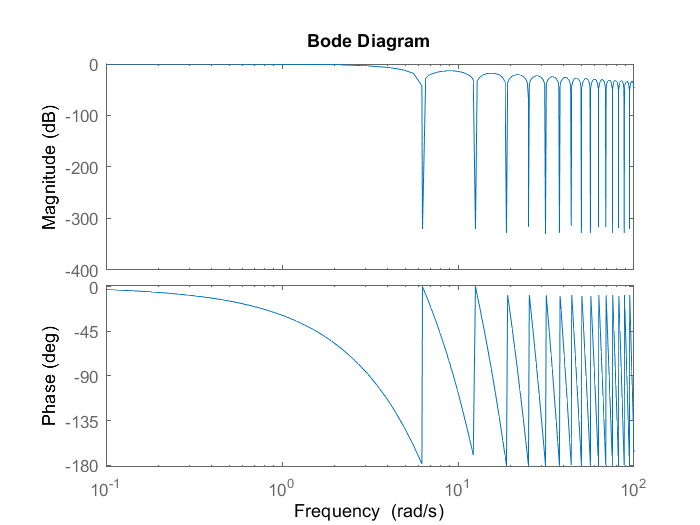

bode(e1-e2)

Learning1

b = [2 3 4];
a = [1 3 3 1];
q = roots(b)

q =   -0.7500 + 1.1990i
  -0.7500 - 1.1990i


p = roots(a)

p =   -1.0000 + 0.0000i
  -1.0000 - 0.0000i
  -1.0000 + 0.0000i


% Gain factor
k = b(1)/a(1)

k = 2

bb = k*poly(q)

bb =     2.0000    3.0000    4.0000


aa = poly(p)

aa =     1.0000    3.0000    3.0000    1.0000


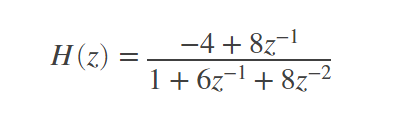

b = [-4 8];
a = [1 6 8];
[r,p,k] = residuez(b,a)

r =    -12
     8


p =     -4
    -2



k =

     []



Zad

A.

syms P(z) p(n) T(z) t(n)
a=0.801;
P(z)=(1-a)/(z-a)

$$P(z) = \frac{199}{1000\,\left(z-\frac{801}{1000}\right)}$$

T(z)=P(z)/(P(z)+1)

$$T(z) = \frac{199}{1000\,\left(z-\frac{801}{1000}\right)\,\left(\frac{199}{1000\,\left(z-\frac{801}{1000}\right)}+1\right)}$$

p(z)=iztrans(P)

$$p(z) = \frac{199\,{\left(\frac{801}{1000}\right)}^{n}}{801}-\frac{199\,\delta_{n,0}}{801}$$

t(z)=iztrans(T)

$$t(z) = \frac{199\,{\left(\frac{301}{500}\right)}^{n}}{602}-\frac{199\,\delta_{n,0}}{602}$$

    b.

k_UO=P(1)

$$k\_UO = 1$$

k_UZ=T(1)

$$k\_UZ = \frac{1}{2}$$

    d.

syms h(n)
h(n)=iztrans(P,1*z/(z-1))

$$h(n) = \frac{199\,{\left(\frac{801}{1000}\right)}^{\frac{z}{z-1}}}{801}-\frac{199\,\delta_{\frac{z}{z-1},0}}{801}$$

        wykres odpowiedzi jednostkowej u(k)=1(k) -> U(z)=z/(z-1)

z=tf('z',0.1);
a=0.801;
P=(1-a)/(z-a)

P =
 
    0.199
  ---------
  z - 0.801
 
Sample time: 0.1 seconds
Discrete-time transfer function.



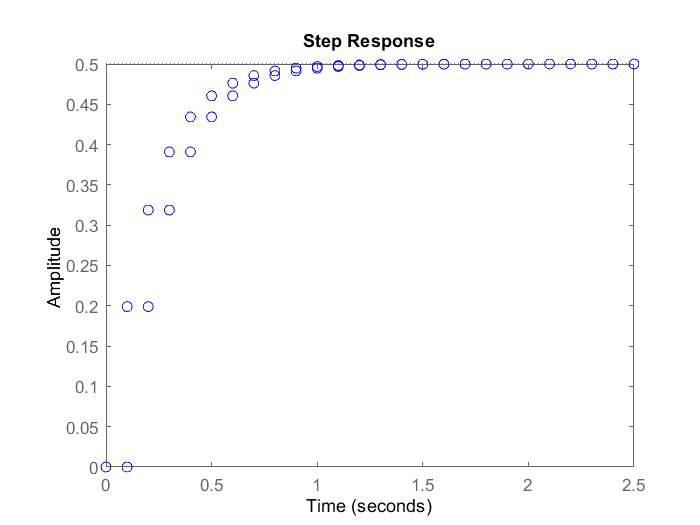

%bode(P)
%step(P)
figure
step(feedback(P,1),"o")

[h,t]=step(feedback(P,1))

h =          0
    0.1990
    0.3188
    0.3909
    0.4343
    0.4605
    0.4762
    0.4857
    0.4914
    0.4948


t =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


t(h>=0.9*0.5)

ans =     0.5000
    0.6000
    0.7000
    0.8000
    0.9000
    1.0000
    1.1000
    1.2000
    1.3000
    1.4000


%legend('UO','UZ')

B.

Uklad zamkniety

z=tf('z',0.1);
a=0.801;
P=(1-a)/(z-a);
[B,A]=tfdata(feedback(P,1),'v')

B =          0    0.1990


A =     1.0000   -0.6020


p=0.7;
m=[0;0;0;0;1;-p]

m =          0
         0
         0
         0
    1.0000
   -0.7000



syms r2 r1 r0 s2 s1 s0 z
% r = [r2 r1 r0 1]
% s = [s2 s1 s0 1]
% a=[1 2]
%conv(r,a)
Ap=poly2sym(A,z);
Bp=poly2sym(B,z);
Rp = poly2sym([r2, r1, r0], z);
Sp = poly2sym([s2, s1, s0], z);
expand(Bp*Sp);
BS=fliplr(coeffs(Bp*Sp,z))

$$BS = \left(\begin{array}{ccc} \frac{199\,s_{2}}{1000} & \frac{199\,s_{1}}{1000} & \frac{199\,s_{0}}{1000} \end{array}\right)$$

expand(Ap*Rp);
AR=fliplr(coeffs(Ap*Rp,z))

$$AR = \left(\begin{array}{cccc} r_{2} & r_{1}-\frac{301\,r_{2}}{500} & r_{0}-\frac{301\,r_{1}}{500} & -\frac{301\,r_{0}}{500} \end{array}\right)$$

BS=[zeros(length(AR)-length(BS)), BS]

$$BS = \left(\begin{array}{cccc} 0 & \frac{199\,s_{2}}{1000} & \frac{199\,s_{1}}{1000} & \frac{199\,s_{0}}{1000} \end{array}\right)$$

M=BS+AR

$$M = \left(\begin{array}{cccc} r_{2} & r_{1}-\frac{301\,r_{2}}{500}+\frac{199\,s_{2}}{1000} & r_{0}-\frac{301\,r_{1}}{500}+\frac{199\,s_{1}}{1000} & \frac{199\,s_{0}}{1000}-\frac{301\,r_{0}}{500} \end{array}\right)$$

X=[0 0 0 0 0 0
 0 0 0 0 0 0
 1 0 0 0 0 0
 -301/500 1 0 199/1000 0 0
 0 -301/500 1 0 199/1000 0
 0 0 -301/500 0 0 199/1000]

X =          0         0         0         0         0         0
         0         0         0         0         0         0
    1.0000         0         0         0         0         0
   -0.6020    1.0000         0    0.1990         0         0
         0   -0.6020    1.0000         0    0.1990         0
         0         0   -0.6020         0         0    0.1990


%RS=[r2;r1;r0;s2;s1;s0]
RS=linsolve(X,-m)

RS =    NaN
   NaN
   NaN
   NaN
   NaN
   NaN


%conv(rp,num)

controlSystemDesigner(tf(1,[1,1]))

% minreal(P/(C*P+1))
% [num,den]=tfdata(P/(C*P+1),'v')
% roots(num)
% roots(den)
% tf(num,den,0.1)